1) Data Loading, Feature extraction, and data splitting:

 The Skin data contains

 column 1: Blue color

 column2:  Green color ,

 column 3: Red color

column 4:  skin =1, non-skin=0

%% Initialization
clear ; close all; clc

%add code here
%% Load Data:
skinFile = load('skin.csv');

%add code here
%extract input features as data_x and output labels as data_y
data_x = skinFile(:,(1:3));
data_y = skinFile(:,4);

%split the data into trining set and test set
%complete the function mySplitData() in mySplitData.m

rate=0.8;

[XTrain XTest yTrain yTest] = mySplitData(data_x, data_y, rate);



## 2)Data Visualization

First plot the positive samples with red dots using scatter3() function

Then plot the negative samples with blu dots using scatter3() function in the same figure. 

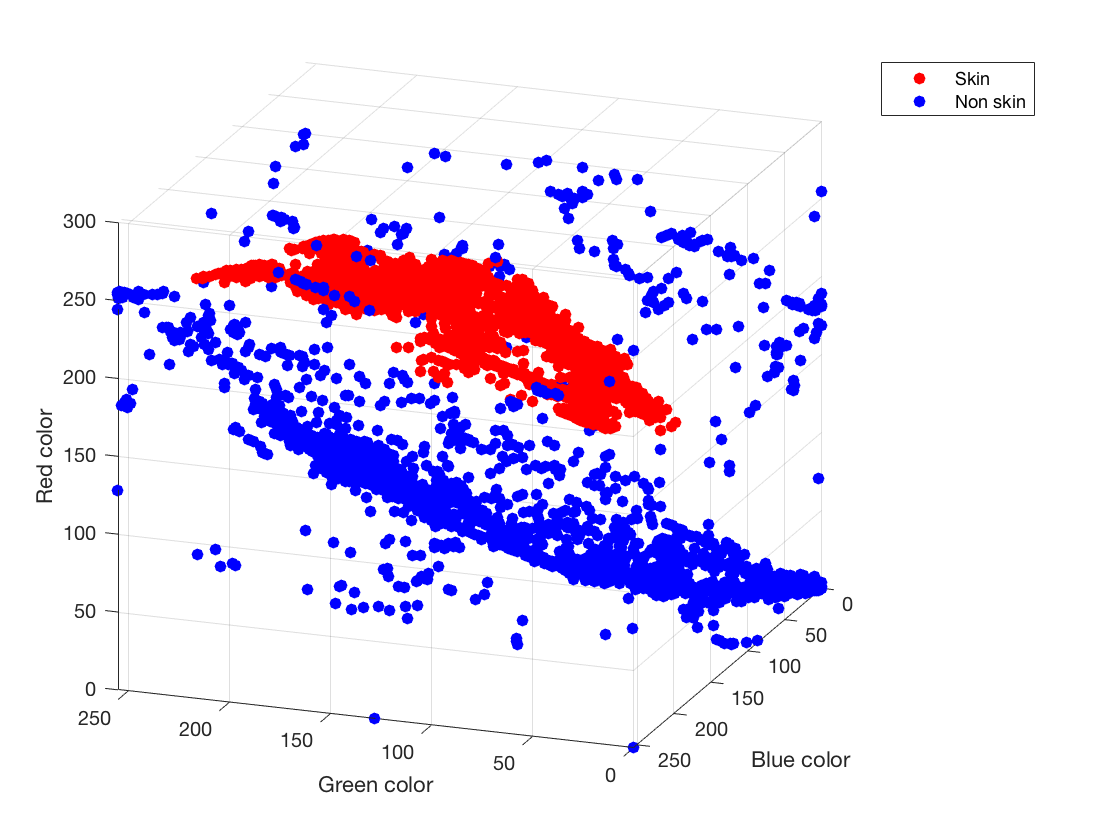

figure(1);

%%add code
% Find Indices of Positive samples
pos = find(yTrain==1);

%make a for loop to populate a skin vector to be ploted will need to be nested bc XTrain is mX3

start = pos(1);
stop = pos(length(pos));

S_Blue = XTrain(start:stop,1);
S_Green = XTrain(start:stop,2);
S_Red = XTrain(start:stop,3);

scatter3(S_Blue,S_Green,S_Red, 'filled','r');

%%add code
% Find Indices of Negative samples

hold all
neg = find(yTrain == 0);

start = neg(1);
stop = neg(length(neg));

NS_Blue = XTrain(start:stop,1);
NS_Green = XTrain(start:stop,2);
NS_Red = XTrain(start:stop,3);

%%add code
% 3d plot for negative samples
scatter3(NS_Blue, NS_Green, NS_Red, 'filled','b');

xlabel('Blue color ')
ylabel('Green color')
zlabel('Red color')

axis([ 0 255 0 255]);

legend('Skin', 'Non skin')


view([-110 -20])

## 3) Data normalization using mean and stadard variation

In machine learning, data normalization is a procedure that m**akes input features are in the similar ranges. **And another reason why data normalization is applied that  **Gradient descent converges much faster with feature scaling than without feature scaling. **

%% Add code:
% %add the lines of code for data normalization
% Use the standardization method whcih uses the mean and the standard deviation of the feature.
% X is a input matrix with size Mxk : M input samples and each sample has k features.
% Each column is a feature and each row is an input sampe data
XTrainMean = mean(XTrain);
XTrainStd=std(XTrain);
XTrainNorm = (XTrain-XTrainMean)./XTrainStd;

**4) ** add an intercept term (Bias term) in the input matrix and Set the Learning rate and the number of iteration

%% Add code:
% add a lines of code to add the bias term into the input matirx

[M,n] = size(XTrainNorm);
bias = ones(M,1);
X = [bias,XTrainNorm];

alpha = 0.01;
iteration = 50000;

## 5): Find parameters using the gradient descent method 

%ADD code:
% complete lines of code for the gradient descent
Cost_J = zeros(iteration, 1);   %cost fucntion J

% add code
%Intialize the weigh with zeros
W=zeros((n+1),1);%should be set to zeros however random/ones works too

for i = 1:iteration
    Z = X*W;
    %predcition calculation  - you need to call sigmoid function to predcit
    y_pred = sigmoid(Z);
    
    
    %Error calculation
    error = y_pred-yTrain;
    
    
    %Partial derivatives calculation
    delta_W=(error'*X)*(1/M);
    
    
    % weight update
    W=W-alpha*delta_W';
    
    k=(yTrain.*log(y_pred))+((1-yTrain).*log(1-y_pred));
    % Add code: save the cost J at each iteration i for the later plotting
    j = sum(k);
    Cost_J(i) = -(1/M).*j;
end
%plot(y_pred, 'o');

## 6) dispaly the Log Loss cost function over the iteration

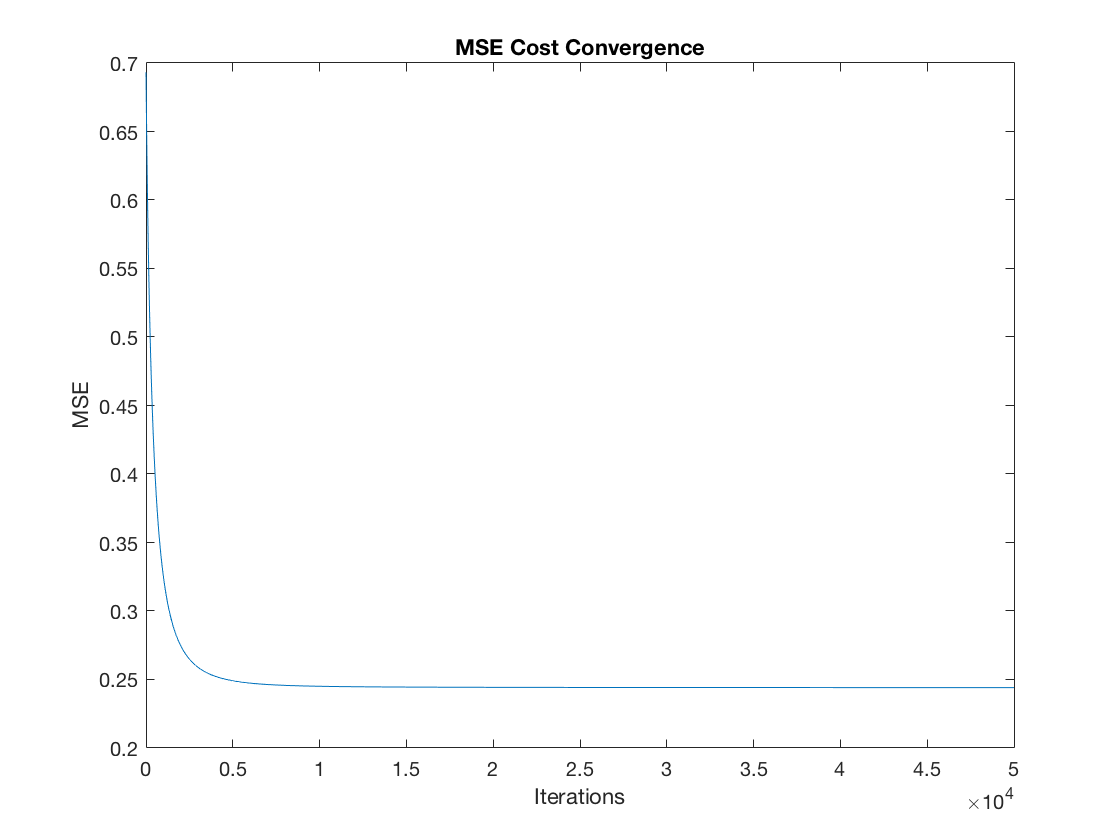

%% Add code:
% %add the lines of code to plot the Logloss MSE cost convergence
figure(2);

%% Add code:
% %add the lines of code to plot the MSE cost convergence

plot(Cost_J);xlabel('Iterations');ylabel('MSE')
title('MSE Cost Convergence');

Make prediction using the trained logisitc regression

## 7) Calculate the training accuracy

%% Add code to calculate the training accuracy
%%  acc = ((Number of Correct Predictions)/(Total Number of Traing Samples))*100
%

%CP = classperf(yTrain, int8(y_pred));%Evaluate performace of classifier --CorrectRate returns acc
temp = int8(y_pred);
TP = 0;
for i = 1:length(y_pred)
    if(temp(i)==yTrain(i))
        TP=TP+1;
    end 
end 
acc = (TP/M)*100;
fprintf("Question 1: what is the accuracy of the developed model on the training data?\nAccuracy = %.2f%", acc)

Question 1: what is the accuracy of the developed model on the training data?
Accuracy = 93.84

## 8) Measure the predcition Model accuracy on the test data

- Normalize the input feature. 

- Add the intercept term (Bias term) in the input vector. 

- Calculate the linear model  Z                               

- Calculate the sigmoid output of the input Z

- If the sigmoid output >= 0.5, the predicted output is  1

- else  (sigmoid output < 0.5) , the predicted output is  0

%%add code


%Normalize the input feature
XTestNorm = (XTest-XTrainMean)./XTrainStd;

%Bias Term
[M,n] = size(XTestNorm);
bias = ones(M,1);
TestData = [bias, XTestNorm];

Z = TestData*W;
Test_Pred = sigmoid(Z);

Test_output = int8(Test_Pred);

Test_temp = int8(Test_Pred);
TP = 0;
for i = 1:length(Test_Pred)
    if(Test_temp(i)==yTest(i))
        TP=TP+1;
    end 
end 
test_acc = (TP/M)*100;
fprintf("Question 2: What is the accuracy of the developed model on the test data set? " + ...
    "\nTest Acc = %.2f%%", test_acc)

Question 2: What is the accuracy of the developed model on the test data set? 
Test Acc = 93.40%

fprintf("Question 3: By comparing both accuracies on the training and the testing sets," + ...
    " do you have any underfitting /overfitting issues?\n based off our accuracy reports it" + ...
    " appears that we have a very generalized logistic classifier. ")

Question 3: By comparing both accuracies on the training and the testing sets, do you have any underfitting /overfitting issues?
 based off our accuracy reports it appears that we have a very generalized logistic classifier. 